% Question 1: must generate 1000 samples from a mixture
% of three multivariate Gaussians with parameters: 
%mu1 = [0,0]';
%mu2 = [3, 0]';
%mu3 = [0, 5]';
%pi = [0.3, 0.5, 0.2]';
mu1 = [0,0];
mu2 = [3, 0];
mu3 = [0, 5];
pi = [0.3, 0.5, 0.2];
sigma1 = [1, 0.5; 0.5, 1];
sigma2 = [1, -0.2; -0.2, 1];
sigma3 = [1, 0.9; 0.9, 1];


% see that dimension D = 2, K = numb mixtures = 3
D = 2; 
K = 3; 

rng('default')
X = sampleGaussianMixture({mu1, mu2, mu3}, {sigma1, sigma2, sigma3})

X =    1.833885014595086  -1.039276257590353
   0.318765239858981  -0.973108664902469
   0.342624466538650   3.270294887896326
  -1.349886940156521   1.953377350306652
  -0.063054873189656   0.587458075293229
  -0.124144348216312   1.228043798190964
   1.417192413429614   1.290129782987838
   0.717238651328838   1.770444500226945
   1.034693009917860   1.146847496102054
   0.293871467096658  -0.534871174469290
  -1.147070106969150  -1.499204023612803
  -2.944284161994896  -0.226468207116673
  -0.754928319169703   0.809249186906345
  -0.102242446085491  -0.260220494743316
   0.312858596637428  -0.592578681307250
  -0.164879019209038   0.461170947535981
   1.109273297614398  -0.193308635085148
   0.600704319018829  -0.751104043429189
  -0.006849328103348   1.323872117532895
   0.371378812760058  -0.009672416684403
  -1.089064295052236  -0.516336556476449
   1.100610217880866   1.887631839272976
  -1.491590310637609  -1.388647403661703
   2.350457224002042   0.642101744033194
  -0.1924185

% Step 1: sample which mixture probability to use
% Step 2: sample X values from N(X | mu_k, sigma_k)


% Generate N samples
N = 1000;
x = zeros(N, D); % N x D matrix, one col per dimension
% so rowwise ,it is one sample of dimension D = 2
mu = {mu1, mu2, mu3}; %cell array
sigma = {sigma1, sigma2 sigma3};

for n = 1:N
    % Step 1: sample k from mixtures probs (pi)
    unifNum = rand; % sample from Unif(0,1)
    k = min(find(unifNum < cumsum(pi)));
   % k = find(unifNum < cumsum(pi), 'first');
    
    % Step 2: sample x-value from multivariate gaussian
    % that has the corresponding parameters, muk, sigmak
    x(n, :) = mvnrnd(mu{k}, sigma{k}); % placing into row
end

x

x =    1.833885014595086   5.665887993530681
   0.318765239858981   4.716880602548527
   0.342624466538650   3.270294887896326
  -1.349886940156521   5.107994222971203
  -0.063054873189656   5.254799822968385
  -0.124144348216312   1.228043798190964
   4.417192413429614   0.374491653746597
   0.717238651328838   1.770444500226945
   4.034693009917860   0.505260469377957
   3.293871467096658  -0.830150754409877
   1.852929893030850  -0.817860868064790
  -2.944284161994896  -0.226468207116673
   2.245071680830296   1.493598551239550
  -0.102242446085491  -0.260220494743316
   3.312858596637429  -0.909977513817653
   2.835120980790962   0.648000828750554
   4.109273297614397  -1.068058151037720
   3.600704319018829  -1.309727761753438
  -0.006849328103348   1.323872117532895
   3.371378812760058  -0.295302434350134
   1.910935704947764   0.249712528819701
   4.100610217880867   1.292890435912105
   1.508409689362391  -0.428986232439329
   2.350457224002042   0.642101744033194
  -0.1924185


% can put rng('default') and run the script and compare
% the random values are the same. 

% Probability density of mixture: 
p = @(x) pi(1) * mvnpdf(x, mu1, sigma1) + ...
    pi(2) * mvnpdf(x, mu2, sigma2) + ... 
    pi(3) * mvnpdf(x, mu3, sigma3)

p = function_handle with value:
    @(x)pi(1)*mvnpdf(x,mu1,sigma1)+pi(2)*mvnpdf(x,mu2,sigma2)+pi(3)*mvnpdf(x,mu3,sigma3)


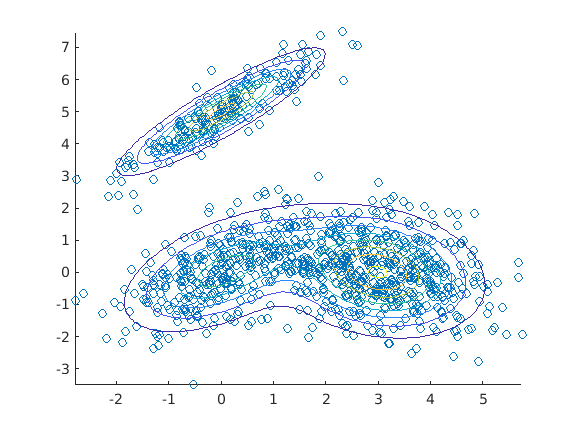

% Sampled data using Scatter plot
clf; 
X1 = x(:, 1);
X2 = x(:, 2);
scatter(X1, X2) % the two dimensions sampled from data

hold on; 


% Deterministic part: mixture function Contour plot : 

% making the grid of values
x1 = linspace(min(X1), max(X1));     % 1 x 100
x2 = linspace(min(X2), max(X2));     % 1 x 100

% joining xx2 on the right of xx1
[xx1 xx2] = meshgrid(x1, x2);        % xx1 is 100 x 100

% get the values from the multivariate pdf using
% the meshgrid
f = p([xx1(:), xx2(:)]);
% size(xx1(:)) = 1000 x 1
% size([xx1(:), xx2(:)]) = 1000 x 2
% size(f) = 1000 x 1

% contour plot 
% note: must reshape f to be 100x100 since both the 
% xx1 and xx2 are 100 x 100. 
contour(xx1, xx2, ...
    reshape(f, 100, 100))